## 레이더 제원 설정

레이더를 구성하는 안테나의 종류와 개수 그리고 배치 방식을 설정합니다.

8개의 코사인 안테나를 동일한 간격(ULA, Uniform Linear Array)으로 배치

antenna=phased.ULA;
antenna.NumElements = 8;
cosineElement = phased.CosineAntennaElement;
antenna.Element = cosineElement;
% viewArray(antenna);

레이더 제원에 따른 신호의 파형 시각화

% pattern(antenna,300e6,-180:180,0,...
%     'Type','directivity',...
%     'PropagationSpeed',3e8);

## 송신 펄스 설정

주파수 변조 방식, PRF, SampleRate 설정

Linear Frequency Modulation(선형 주파수 변조) 사용

초당 1,000번의 펄스 반복

초당 1,000,000번의 측정 > 펄스당 1,000개의 측정값 생성

waveform=phased.LinearFMWaveform;
waveform.SampleRate = 1e6;
waveform.PRF=1000;
waveform.PulseWidth=1e-4;

nSamples = waveform.SampleRate/waveform.PRF;

송신 펄스 시각화

% y = step(waveform);
% t = (0:nSamples-1)/waveform.SampleRate;
% figure;
% plot(t,real(y));title('Radar Waveform'); xlabel('Time (sec)'); ylabel('Amplitude')

## 송신부 설정

송신 신호 강도 설정

TX=phased.Transmitter('Gain',20);

## 타겟 설정

타겟의 좌표, 속도

타겟 = 목표 인스턴스, 플랫폼 = 시뮬레이션 인스턴스 (iterator 생성과 유사)

TgtModel=phased.RadarTarget;
tgtpos=[10e3*sqrt(2);10e3*sqrt(2);0];  % Target at 20 km distance, 30 degree azimuth
tgtvel=[75*sqrt(3);75;0];      % Radial velocity is 150 m/sec

% Platform Specs
PlatformModel=phased.Platform;
PlatformModel.InitialPosition = tgtpos;
PlatformModel.Velocity = tgtvel;

## 채널 설정

ChannelModel = phased.FreeSpace;
ChannelModel.TwoWayPropagation=true;

## 송신 신호, 수신 신호 배열 생성

txArray = phased.Radiator(...
    'Sensor',antenna,...
    'OperatingFrequency',300e6);
rxArray = phased.Collector(...
    'Sensor',antenna,...
    'OperatingFrequency',300e6);
rxPreamp = phased.ReceiverPreamp('Gain',10,'NoiseFigure',5,...
    'SampleRate',1e6);

## 변수 정의

레이더 위치, 속도, 펄스 수, 데이터큐브 생성

정지된 레이더

32개의 펄스 관찰

0으로 초기화된 1000*8*32 형태의 데이터 큐브

radarPos = [0;0;0];
radarVel = [0;0;0];
nPulses = 64;

tgtAng = zeros(2,nPulses);

datacube = complex(zeros(nSamples,antenna.NumElements,nPulses));

## 신호 생성 및 레코딩

"The radar data cube consists of the complex IQ data samples that are collected at the array for each pulse. The dimensions are 1000 time samples, by 8 receive elements, by 32 pulses (the number of pulses in our coherent processing interval for this example)."

위에서 생성한 모든 값 (waveform, target 등) 을 종합하여 datacube에 펄스단위로 데이터 생성/기록

for ii=1:nPulses
    wf=step(waveform);
    [tgtPos, tgtVel] = step(PlatformModel,1/waveform.PRF);
    [tgtRng, tgtAng] = rangeangle(tgtPos, radarPos);

    s0 = step(TX, wf);
    s1 = step(txArray,s0, tgtAng);
    s2 = step(ChannelModel, s0, radarPos, tgtPos, radarVel, tgtVel);
    s3 = step(TgtModel, s2);
    s4 = step(rxArray,s3,tgtAng);
    s5 = step(rxPreamp,s4);
    datacube(:,:,ii) = s5(:,:);

end

## 수신 신호 부분 시각화

antenna_idx : 안테나 인덱스 (1<=antenna_idx<=antenna.NumElements)

pulse_idx : 펄스 인덱스 (1<=pulse_idx<=num_pulse)

% antenna_idx = 4;
% pulse_idx =21;
% 
% t = ((pulse_idx-1)*nSamples:pulse_idx*nSamples-1)/waveform.SampleRate;
% y = abs(datacube(:, antenna_idx, pulse_idx));
% 
% figure;
% plot(t,y(:));
% title(['Reflected Signal ~ antenna: ', num2str(antenna_idx),', ','pulse: ', num2str(pulse_idx)]);
% xlabel('Time (sec)'); ylabel('Magnitude')

## 메모리 초기화 (답안 제거)

- 생성한 원천데이터 - datacube

- 레이더 제원값 - antenna, waveform, nPulses

        제외한 모든 변수 할당 해제

clearvars -except datacube antenna waveform nPulses

nSamples = waveform.SampleRate/waveform.PRF;

## 펄스 압축

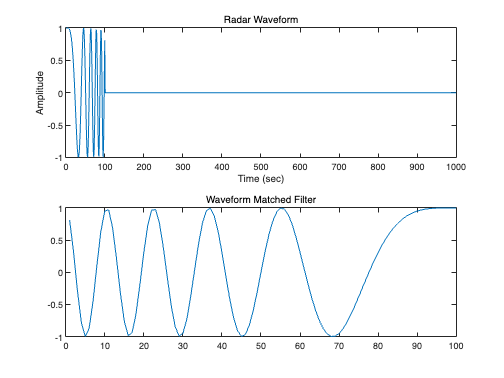

wf = waveform();

references = getMatchedFilter(waveform);
matchedfilter = phased.MatchedFilter(...
    'Coefficients',references,...
	'SpectrumWindow','Hamming');

matchFiltered = step(matchedfilter,datacube);

figure;
subplot(2,1,1);plot(real(wf));title('Radar Waveform'); xlabel('Time (sec)'); ylabel('Amplitude')
subplot(2,1,2);plot(real(references));title('Waveform Matched Filter');

## 펄스 압축 전후 비교

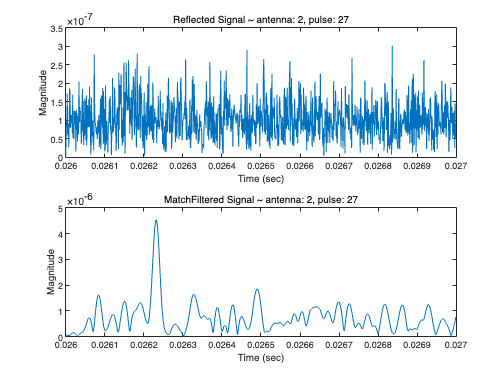

antenna_idx = 2;
pulse_idx =27;

t = ((pulse_idx-1)*nSamples:pulse_idx*nSamples-1)/waveform.SampleRate;
y = datacube(:, antenna_idx, pulse_idx);
filtered_y = matchFiltered(:, antenna_idx, pulse_idx);

figure;
subplot(2,1,1);plot(t,abs(y(:)));
title(['Reflected Signal ~ antenna: ', num2str(antenna_idx),', ','pulse: ', num2str(pulse_idx)]);
xlabel('Time (sec)'); ylabel('Magnitude')

subplot(2,1,2);plot(t,abs(filtered_y(:)));
title(['MatchFiltered Signal ~ antenna: ', num2str(antenna_idx),', ','pulse: ', num2str(pulse_idx)]);
xlabel('Time (sec)'); ylabel('Magnitude')

## 거리 측정

�수신 신호의 피크 측정 시간을 통해 거리를 계산

ind: nSamples 중 피크에 해당하는 측정값 인덱스

length(references): 송신 시간(에 해당하는 측정값 구간의 크기) 

[m,ind] = max(abs(matchFiltered(:,antenna_idx,pulse_idx)));
range_pred = time2range((ind-length(references)-1)/waveform.SampleRate, physconst('LightSpeed'))

range_pred = 1.9786e+04

## 방위각 계산

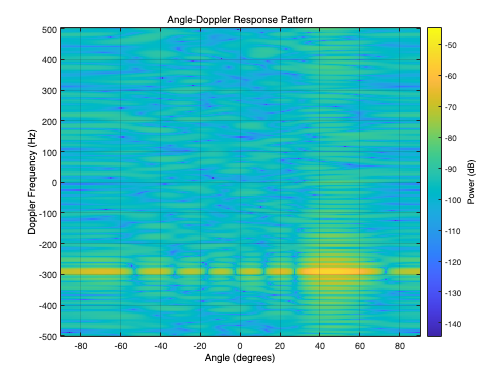

matched=permute(matchFiltered,[1,3,2]);

dd = squeeze(matched(ind,:,:)).';
angleDopplerResp = phased.AngleDopplerResponse('SensorArray',antenna,...
    'OperatingFrequency',3e8, ...
    'PropagationSpeed',physconst('LightSpeed'),...
    'PRF',waveform.PRF, 'ElevationAngle',0);

figure;
plotResponse(angleDopplerResp,dd);

## 방위각 출력

[RESP,ANG_GRID,DOP_GRID] = step(angleDopplerResp,dd);
[max_value, max_index] = max(RESP,[],"all");
angle_idx = fix(max_index/length(RESP));
azimuth_pred = ANG_GRID(angle_idx)

azimuth_pred = 44.1176

## 빔포밍

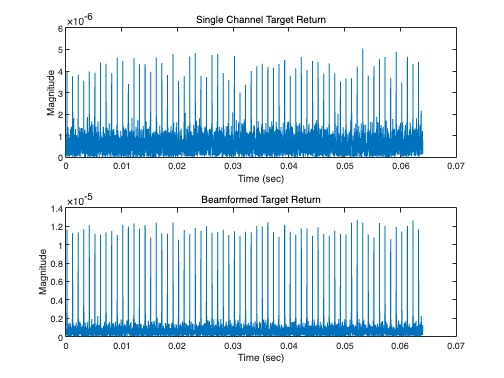

beamformer=phased.PhaseShiftBeamformer;
beamformer.SensorArray=antenna;
beamformer.DirectionSource='Input port';
beamformer.WeightsOutputPort=true;
beamformer.WeightsNormalization='Preserve power';

beamformed=complex(zeros(nSamples,nPulses));
for ii=1:nPulses
    beamformed(:,ii)=step(beamformer,squeeze(matchFiltered(:,:,ii)),[azimuth_pred;0]);
end
figure; 
t = (0:nPulses*nSamples-1)/waveform.SampleRate;
y = abs(reshape(beamformed,nPulses*nSamples,1));
dc=abs(reshape(matchFiltered(:,1,:),nPulses*nSamples,1));
subplot(2,1,1);plot(t,dc);title('Single Channel Target Return'); xlabel('Time (sec)'); ylabel('Magnitude')
subplot(2,1,2);plot(t,y);title('Beamformed Target Return'); xlabel('Time (sec)'); ylabel('Magnitude')

## 속도 측정

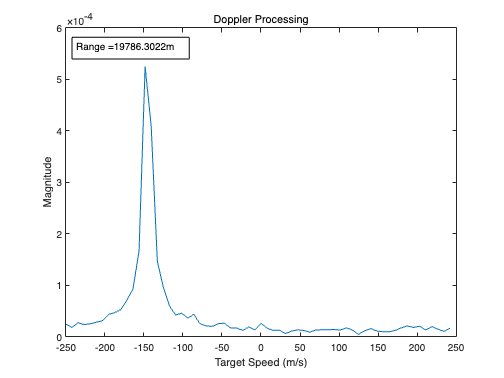

dopplered = fftshift(fft(beamformed(ind,:).')); % Take the fft at the max amplitude range bin 
lambda=physconst('LightSpeed')/300e6;

h5 = figure;
f = (-waveform.PRF/2:waveform.PRF/nPulses:waveform.PRF/2-waveform.PRF/64);
v = f*lambda/2;
plot(v,abs(dopplered)); title('Doppler Processing'); xlabel('Target Speed (m/s)'); ylabel('Magnitude');
annotation(h5,'textbox',...
    [0.142657579062161 0.836671802773498 0.151671755725191 0.0647149460708782],...
    'String',strcat('Range = ',num2str(range_pred),'m'),...
    'FitBoxToText','on');

속도 수치화

[vel_max, vel_idx] = max(abs(dopplered));
velocity_pred = v(vel_idx)

velocity_pred = -148.3348

## RV Map

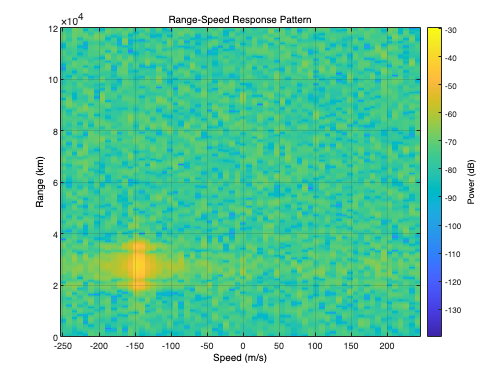

figure;
rangeDoppler=phased.RangeDopplerResponse;
rangeDoppler.DopplerOutput='Speed';
plotResponse(rangeDoppler,beamformed,references)
ylabel('Range (km)');
ylim([0 12e4])

## Output (Prediction)

azimuth_pred

azimuth_pred = 44.1176

velocity_pred

velocity_pred = -148.3348

range_pred

range_pred = 1.9786e+04